%% Simulation of linear system of monocopter with flaps 
% clc
% clear all
% close all
 
% load ka_flap.mat
% load ka_flap_NDI.mat

%% Parameters
J = 3.2284E-6; % moment of inertia of the rotor
b = 3.5077E-6; % motor viscous friction constant 
K = 0.0274; % electromotive force constant, motor torque constant 
R = 4; % electric resistance 
L = 2.75E-6; % electric inductance  
Jxx = 0.0005713669; % symmetrical so most of it is abt x so therefore Jxx
Jzz = 0.0005982825;
plot_variable = 1;
pitch = 25.61; % deg
pitch = abs(pitch);
% (bod pitch * ka * motor rpm) contributes to lift force for disk torque due to total pitch generated
ka = 0.0278; % 1.2180/12180 - min of 1.2180 
ka = ka*plot_variable; % x1, x2, x3, x4, x5...all the way to x13, default is x 10
rps = -40.9663;
rps_squared = rps^2;
cl = 0.11; % naca 0006
cd = 0.023; % naca 0006
g = 9.81;
rho = 1.225;
radius = 0.26;
chord_length = 0.12;
mass = 0.053; % added servo and rods
altitude = 1.25;

% for x:
% 1.5 - 0.5
% 1.25 - 0.5
% 1.0 - 0.5

% for y:
% 2.0 -  0.85
% 1.75 - 0.9 
% 1.5 - 0.95
% 1.25 - 1.05
% 1.0 - 1.2

torque_w_mass = radius*((cl*pitch*ka*rps_squared*rho*chord_length*(radius^3))/(6));
drag_rotation = (cd*pitch*ka*rps_squared*rho*chord_length*(radius^3))/(6*mass);
moving_axis = 'y';

if moving_axis == 'x'
    com = 1/(-(g + drag_rotation)); % omega abt y is negative (roll) linear acc x
elseif moving_axis == 'y'
    com = 1/((g + drag_rotation)); % omega abt x is positive (pitch) linear acc y
end

linesize = 3;
Fontsize = 10;

t = 0:0.01:5;
% monocopter precession is like a speed booster lol
if moving_axis == 'x'   
    u3 = 1/3*(sin((2.2*t)-(pi/2))); % omega abt y, linear acc x
    u = sin((2.2*t)-(pi/2)); % omega abt y, linear acc x  
elseif moving_axis == 'y'   
    u3 = 1/3*sin((2.5*t)-(pi)); % omega abt x, linear acc y
    u = sin((2.5*t)-(pi)); % omega abt x, linear acc y
end


%% servo and angular acceleration feedback
omega_dot = torque_w_mass/Jxx;
s = tf('s');
servo = 0.28*K/(s*((J*s+b)*(L*s+R)+K^2)); % includes the integral to positional angle alrd
H_servo = 3.54;
H_omega_dot_tf = 1; % lpf is needed and tuned here for indi, ndi is better only  
stf = servo/(1+(servo*H_servo));
% stf = feedback(servo,1);
% isstable(stf)
% pole(stf)
%omega_dot_tf = stf; % ndi
omega_dot = stf*omega_dot;
% omega_dot_tf = omega_dot/(1+(omega_dot*H_omega_dot_tf)); % indi
% isstable(omega_dot_tf)
% pole(omega_dot_tf)

[omega_dot_controller,info] = pidtune(omega_dot,'PID');
omega_dot_tf = feedback(omega_dot_controller*omega_dot,1); % implement feedback for tf which is servo to become servo/(1+(servo*H)
% isstable(omega_dot_tf)
% pole(omega_dot_tf)

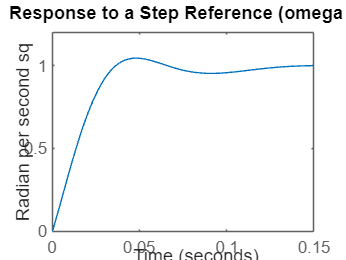

% to simulate step input of a single servo angle
st = 0:0.001:0.15;
% Config = RespConfig('Amplitude',3.5+0.04);
% step(stf, st, Config) % step function here is in the form of a servo angle 
% ylabel('Position, \theta (radians)')
% title('Response to a Step Reference (servo)')

%% for omega_dot_tf
Config = RespConfig('Amplitude',1); 
step(omega_dot_tf, st, Config) 
ylabel('Radian per second sq')
title('Response to a Step Reference (omega dot)')

%% to simulate disturbance step input

% [omega_dot_pi,info_d] = pidtune(stf*torque_w_mass,'PID')
disturbance_torque_tf = 1/(Jxx+(omega_dot_controller*H_omega_dot_tf*stf*torque_w_mass)); % w feedback
%disturbance_torque_tf = ((s^2)*com)/(((s^2)*com)+(H_omega_dot_tf*omega_dot)) % w feedback
% disturbance_torque_tf = 1/Jxx % wo feedback
dt = 0:0.001:0.3;
isstable(disturbance_torque_tf)

ans = logical
   0


pole(disturbance_torque_tf)

ans = 1.0e+06 *

   0.0000 + 0.0000i
  -1.4545 + 0.0000i
  -1.4545 + 0.0000i
  -0.0000 + 0.0001i
  -0.0000 - 0.0001i
  -0.0001 + 0.0000i
  -0.0000 + 0.0000i


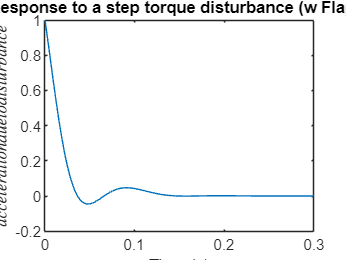

Config = RespConfig('Amplitude',1);
disturbance = step(disturbance_torque_tf, dt, Config); % step function here is in the form of a servo angle 
plot(dt,disturbance/(1/Jxx))
ylabel('$\frac{acceleration output}{acceleration due to disturbance}$','Interpreter','latex','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Response to a step torque disturbance (w Flaps)')

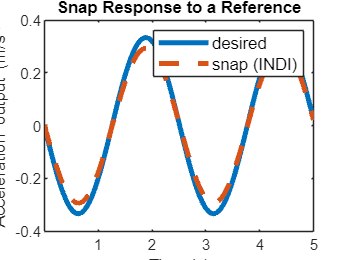

% snap
snap = (s^2)*com*omega_dot*(1/(s^2))*1/com; % snap only
%[snap_controller,snap_info] = pidtune(snap,'PD'); % controller only needed for omega abt y, linear acc x
snap_tf = feedback(snap,1); % jerk and snap INDI
% isstable(snap_tf)
% pole(snap_tf)

snap_indi = lsim(snap_tf,u3,t); % INDI
snap_ndi = lsim(snap,u3,t); % NDI very big
plot (t,u3,'LineWidth',linesize)
hold on
plot(t,snap_indi,'lineStyle','--','LineWidth',linesize)
% plot(t,snap_ndi,'lineStyle','--','LineWidth',linesize) % NDI can be tested
hold off
xlim([0.011 5])

ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Snap Response to a Reference','FontSize',Fontsize)
legend('desired','snap (INDI)','FontSize',Fontsize)

% snap + jerk
D = 0*plot_variable; 
omega = (s+D)*com*omega_dot_tf*(1/(s^2))*1/com; % jerk only
[omega_controller,omega_info] = pidtune(omega,'P')

omega_controller =
 
  Kp = 41.7
 
P-only controller.
Model Properties


omega_info = struct with fields:
                Stable: 1
    CrossoverFrequency: 40.6667
           PhaseMargin: 59.9998


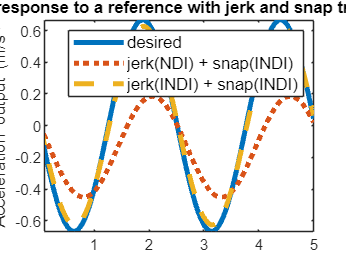

omega_tf_ndi = omega; % jerk and snap NDI
omega_tf = feedback(omega_controller*omega,1); % jerk and snap INDI
% isstable(omega_tf)
% pole(omega_tf)


jerk = lsim(omega_tf,u3,t);
jerk_ndi = lsim(omega_tf_ndi,u3,t);
plot (t,u3*2,'LineWidth',linesize)
hold on
plot(t,jerk_ndi + snap_indi,'lineStyle',':','LineWidth',linesize)
plot(t,jerk+snap_indi,'lineStyle','--','LineWidth',linesize)
%plot(t,jerk+snap+gyro_y_flap,'LineWidth',linesize) % linear acc y
%plot(t,jerk+snap+gyro_x_flap,'LineWidth',linesize) % linear acc x
hold off
xlim([0.1 5])

ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Flap response to a reference with jerk and snap tracking','FontSize',Fontsize)
legend('desired','jerk(NDI) + snap(INDI)','jerk(INDI) + snap(INDI)','FontSize',Fontsize)

% quat u3
angle = com*omega_dot_tf*(1/(s^2))*1/com;
[angle_controller,angle_info] = pidtune(angle,'PD')

angle_controller =
 
             
  Kp + Kd * s
             

  with Kp = 122, Kd = 24.2
 
Continuous-time PD controller in parallel form.
Model Properties


angle_info = struct with fields:
                Stable: 1
    CrossoverFrequency: 23.5449
           PhaseMargin: 60.0000


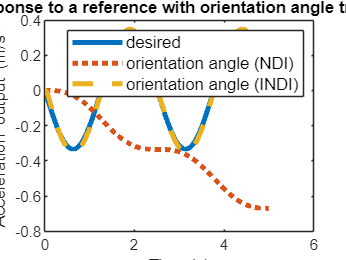

angle_tf = feedback(angle_controller*angle,1);
angle_tf_ndi = angle;
% isstable(angle_tf)
% pole(angle_tf)

quat_3 = lsim(angle_tf,u3,t);
quat_ndi_3 = lsim(angle_tf_ndi,u3,t);
plot (t,u3,'LineWidth',linesize)
hold on
plot(t,quat_ndi_3,'lineStyle',':','LineWidth',linesize)
plot(t,quat_3,'lineStyle','--','LineWidth',linesize)
hold off

ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Flap response to a reference with orientation angle tracking u3','FontSize',Fontsize)
legend('desired','orientation angle (NDI)','orientation angle (INDI)','FontSize',Fontsize)

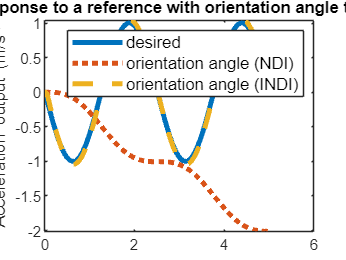

% quat u1
quat = lsim(angle_tf,u,t);
quat_ndi = lsim(angle_tf_ndi,u,t);
plot (t,u,'LineWidth',linesize)
hold on
plot(t,quat_ndi,'lineStyle',':','LineWidth',linesize)
plot(t,quat,'lineStyle','--','LineWidth',linesize)
hold off

ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
xlabel('Time (s)','FontSize',Fontsize)
title('Flap response to a reference with orientation angle tracking u','FontSize',Fontsize)
legend('desired','orientation angle (NDI)','orientation angle (INDI)','FontSize',Fontsize)

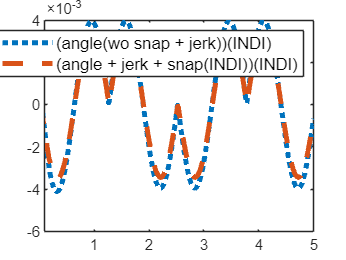

%% compute precession
% compute when linear acc x
if moving_axis == 'x' 
    t_t = transpose(t);
    dydx_quat_y = gradient(quat(:)) ./ gradient(t_t(:));
    dydx_jerk_y = gradient(jerk+snap_indi+quat_3(:)) ./ gradient(t_t(:));

    dydx_quat_y = (dydx_quat_y*Jxx)/(rps*Jzz);
    dydx_jerk_y = (dydx_jerk_y*Jxx)/(rps*Jzz);
 
    precession_radius_y_jerk = abs(altitude*tan((jerk+snap_indi+quat_3)*com));
    precession_radius_y_quat = abs(altitude*tan((quat)*com));

    gyro_y_flap_quat = dydx_quat_y.*precession_radius_y_quat;
    gyro_y_flap = dydx_jerk_y.*precession_radius_y_jerk;
    
    plot(t,gyro_y_flap_quat,'lineStyle',':','LineWidth',linesize) 
    hold on
    plot (t,gyro_y_flap,'lineStyle','--','LineWidth',linesize)
    hold off
    legend('(angle(wo snap + jerk))(INDI)','(angle + jerk + snap(INDI))(INDI)','FontSize',Fontsize)
    xlim([0.1 5])

% compute when linear acc y
elseif moving_axis == 'y' % negative one added to sync w the derivatives obtained from test_aux in exp_flat, scaled it through the other axis' signal
    t_t = transpose(t);
    dydx_quat_x = gradient(quat(:)) ./ gradient(t_t(:));
    dydx_jerk_x = gradient(jerk+snap_indi+quat_3(:)) ./ gradient(t_t(:));

    dydx_quat_x = -1*(dydx_quat_x*Jxx)/(rps*Jzz);
    dydx_jerk_x = -1*(dydx_jerk_x*Jxx)/(rps*Jzz);
 
    precession_radius_x_jerk = abs(altitude*tan((jerk+snap_indi+quat_3)*com));
    precession_radius_x_quat = abs(altitude*tan((quat)*com));

    gyro_x_flap_quat = dydx_quat_x.*precession_radius_x_quat;
    gyro_x_flap = dydx_jerk_x.*precession_radius_x_jerk;
    
    plot(t,gyro_x_flap_quat,'lineStyle',':','LineWidth',linesize) 
    hold on
    plot (t,gyro_x_flap,'lineStyle','--','LineWidth',linesize)
    hold off
    legend('(angle(wo snap + jerk))(INDI)','(angle + jerk + snap(INDI))(INDI)','FontSize',Fontsize)
    xlim([0.1 5])
end

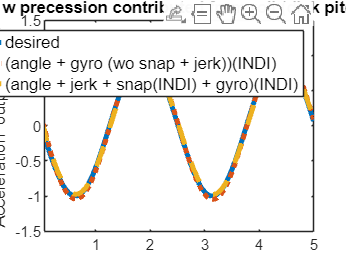

% all together w gyro, 
% for linear acc x, starting pt leads by pi/2, so contributor linear y (pitch) one lags behind by pi/2, in derivatives section somehow its accounted for alrd lol
% for linear acc y, starting pt leads by pi/2, so contributor linear x (roll) one lags behind by pi/2, in derivatives section somehow its accounted for alrd lol 
if moving_axis == 'x'
    plot (t,u,'LineWidth',linesize)
    hold on
    plot(t,quat+gyro_x_flap_quat,'lineStyle',':','LineWidth',linesize) % linear acc x  
    plot(t,jerk+snap_indi+quat_3+gyro_x_flap,'lineStyle','--','LineWidth',linesize) % linear acc x
    hold off
    flap_x = jerk+snap_indi+quat_3+gyro_x_flap;
    xlim([0.07 5]) % linear acc x
      
    ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
    xlabel('Time (s)','FontSize',Fontsize)
    %xticklabels({'0.5','1','1.5','2','2.5','3','3.5','4','4.5','5'})
    % in the pitch, you will finally understand why i needed to invert the input to make it go ccw instead of its current cw due to precession
    title('Flap response to a reference w precession contributed from pitch (disk roll, moving along world x axis)','FontSize',Fontsize)
    legend('desired','(angle + gyro (wo snap + jerk))(INDI)','(angle + jerk + snap(INDI) + gyro)(INDI)','FontSize',Fontsize)

elseif moving_axis == 'y' 
    plot (t,u,'LineWidth',linesize)
    hold on   
    plot(t,quat+gyro_y_flap_quat,'lineStyle',':','LineWidth',linesize) % linear acc y
    plot(t,jerk+snap_indi+quat_3+gyro_y_flap,'lineStyle','--','LineWidth',linesize) % linear acc y
    hold off
    flap_y = jerk+snap_indi+quat_3+gyro_y_flap;
    xlim([0.07 5]) % linear acc y
    
    ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
    xlabel('Time (s)','FontSize',Fontsize)
    % xticklabels({'0.25','0.5','1','1.5','2','2.5','3','3.5','4'})
    % in the pitch, you will finally understand why i needed to invert the input to make it go ccw instead of its current cw due to precession
    title('Flap response to a reference w precession contributed from roll (disk pitch, moving along world y axis)','FontSize',Fontsize)
    legend('desired','(angle + gyro (wo snap + jerk))(INDI)','(angle + jerk + snap(INDI) + gyro)(INDI)','FontSize',Fontsize)
end

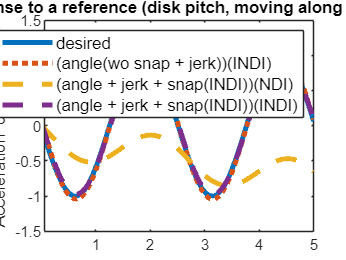

% all together
plot (t,u,'LineWidth',linesize)
hold on
plot(t,quat,'lineStyle',':','LineWidth',linesize) 
plot(t,jerk_ndi+snap_indi+quat_ndi_3,'lineStyle','--','LineWidth',linesize)
plot(t,jerk+snap_indi+quat_3,'lineStyle','--','LineWidth',linesize) 
hold off


if moving_axis == 'x'
    ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
    xlabel('Time (s)','FontSize',Fontsize)
    title('Flap response to a reference (disk roll, moving along world x axis)','FontSize',Fontsize)
    legend('desired','(angle(wo snap + jerk))(INDI)','(angle + jerk + snap(INDI))(NDI)','(angle + jerk + snap(INDI))(INDI)','FontSize',Fontsize)
    xlim([0.07 5])


elseif moving_axis == 'y'
    ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
    xlabel('Time (s)','FontSize',Fontsize)
    title('Flap response to a reference (disk pitch, moving along world y axis)','FontSize',Fontsize)
    legend('desired','(angle(wo snap + jerk))(INDI)','(angle + jerk + snap(INDI))(NDI)','(angle + jerk + snap(INDI))(INDI)','FontSize',Fontsize)    
    xlim([0.07 5])

end


%jerk_scaling_factor_x = abs(mean(transpose((jerk+snap+quat_3)./gyro_y_flap))); % linear acc x
%jerk_scaling_factor_y = mean(transpose((jerk+snap+quat_3)./gyro_x_flap)); % linear acc y
 

%ka_flap_values = zeros(501,10);
%ka_flap_values(:,plot_variable) = jerk+snap+gyro_y_flap;


% plot (t,u,'LineWidth',linesize)
% hold on
% for i = 1:10
%     plot(t,ka_flap_values(:,i),'LineWidth',linesize)
% end    
% hold off
% ylabel('Response','FontSize',Fontsize)
% xlabel('Time(seconds)','FontSize',Fontsize)
% title('Responses to different ka values (INDI)','FontSize',Fontsize)
% legend('desired','x1','x2','x3','x4','x5','x6','x7','x8','x9','x10') 

%ka_flap_values_NDI = zeros(501,10);
%ka_flap_values_NDI(:,plot_variable) = jerk_ndi+snap;

% plot (t,u,'LineWidth',linesize)
% hold on
% for i = 1:10
%     plot(t,ka_flap_values_NDI(:,i),'LineWidth',linesize)
% end    
% hold off
% ylabel('Response','FontSize',Fontsize)
% xlabel('Time(seconds)','FontSize',Fontsize)
% title('Responses to different ka values (NDI)','FontSize',Fontsize)
% legend('desired','x1','x2','x3','x4','x5','x6','x7','x8','x9','x10') 






%% compute precession (old method)
% compute when linear acc x
% if moving_axis == 'x' % negative one added to sync w the derivatives obtained from test_aux in exp_flat 
%     precession_jerk_snap_gyro_y_flap = 1*(((s+D)*com*omega_dot_tf*s*Jxx)+((s^2)*com*omega_dot*s*Jxx))/(Jzz*rps);
%     precession_quat_3_gyro_y_flap = 1*((com*omega_dot_tf*s*Jxx))/(Jzz*rps);
%     precession_quat_gyro_y_flap = 1*((com*omega_dot_tf*s*Jxx))/(Jzz*rps);
%     precession_jerk_snap_gyro_y_flap = lsim(precession_jerk_snap_gyro_y_flap,jerk_scaling_factor_x.*(2/3*sin((2.5*t)-(pi))),t); % linear acc y
%     precession_quat_3_gyro_y_flap = lsim(precession_quat_3_gyro_y_flap,jerk_scaling_factor_x.*(1/3*sin((2.5*t)-(pi))),t);
%     precession_quat_gyro_y_flap = lsim(precession_quat_gyro_y_flap,jerk_scaling_factor_x.*(sin((2.5*t)-(pi))),t);
% 
%     precession_radius_y_jerk = abs(altitude*tan((jerk+snap_indi+quat_3)*com));
%     precession_radius_y_quat = abs(altitude*tan((quat)*com));
% 
%     gyro_y_flap = precession_jerk_snap_gyro_y_flap + precession_quat_3_gyro_y_flap;
%     gyro_y_flap_quat = precession_quat_gyro_y_flap;
% 
%     gyro_y_flap = gyro_y_flap.*precession_radius_y_jerk;
%     gyro_y_flap_quat = gyro_y_flap_quat.*precession_radius_y_quat;
% 
% 
%     % gyro_y_flap = (((jerk+snap+quat_3)*radius*Jxx))/(Jzz*rps); % add this to acc_y
%     % gyro_y_flap_quat = (((quat)*radius*Jxx))/(Jzz*rps); % add this to acc_y
% 
% % compute when linear acc y
% elseif moving_axis == 'y' % negative one added to sync w the derivatives obtained from test_aux in exp_flat, scaled it through the other axis' signal
%     precession_jerk_snap_gyro_x_flap = -1*(((s+D)*com*omega_dot_tf*s*Jxx)+((s^2)*com*omega_dot*s*Jxx))/(Jzz*rps)
%     precession_quat_3_gyro_x_flap = -1*((com*omega_dot_tf*s*Jxx))/(Jzz*rps);
%     precession_quat_gyro_x_flap = -1*((com*omega_dot_tf*s*Jxx))/(Jzz*rps);
%     precession_jerk_snap_gyro_x_flap = lsim(precession_jerk_snap_gyro_x_flap,jerk_scaling_factor_y.*(2*1/3*(sin((2.2*t)-(pi/2)))),t); % linear acc y
%     precession_quat_3_gyro_x_flap = lsim(precession_quat_3_gyro_x_flap,jerk_scaling_factor_y.*(1/3*(sin((2.2*t)-(pi/2)))),t);
%     precession_quat_gyro_x_flap = lsim(precession_quat_gyro_x_flap,jerk_scaling_factor_y.*((sin((2.2*t)-(pi/2)))),t);
% 
%     precession_radius_x_jerk = abs(altitude*tan((jerk+snap_indi+quat_3)*com));
%     precession_radius_x_quat = abs(altitude*tan((quat)*com));
% 
%     gyro_x_flap = precession_jerk_snap_gyro_x_flap + precession_quat_3_gyro_x_flap;
%     gyro_x_flap_quat = precession_quat_gyro_x_flap;
% 
%     gyro_x_flap = gyro_x_flap.*precession_radius_x_jerk;
%     gyro_x_flap_quat = gyro_x_flap_quat.*precession_radius_x_quat;
% 
%     % plot (t, 2/3*(sin((2.2*t)-(pi/2))),'LineWidth',linesize)
%     % hold on
%     plot(t, gyro_x_flap,'lineStyle','--','LineWidth',linesize) % linear acc x
%     % hold off
%     ylabel('Acceleration output (m/s^2)','FontSize',Fontsize)
%     xlabel('Time (s)','FontSize',Fontsize)
%     % in the pitch, you will finally understand why i needed to invert the input to make it go ccw instead of its current cw due to precession
%     title('Gyro produced along linear y','FontSize',Fontsize)
% 
%     xlim([0.20 5])
%     % gyro_x_flap  = (-1*((jerk+snap+quat_3)*radius*Jxx))/(Jzz*rps); % add this to acc_x
%     % gyro_x_flap_quat  = (-1*((quat)*radius*Jxx))/(Jzz*rps); % add this to acc_x
% 
% end